# Communication Systems - CHW2 - Q1 - Amplitude Modulation

clc; clear; close all;

## PART 1

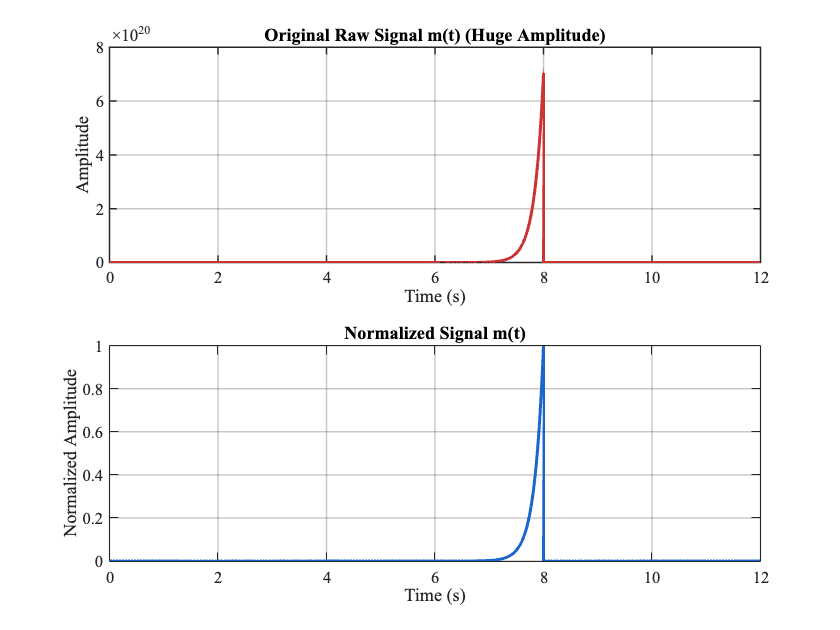

% Sampling frequency
Fs = 20000;              % Sampling Frequency (Hz)
T_start = 0;
T_end = 12;             % Time duration
t = T_start:1/Fs:T_end; % Time vector

% Signal Generation
% Signal Definition: m(t) = e^(-6t)*(u(t-4)-u(t-8)) + e^(6t)*(u(t-4)-u(t-8))
% Create the window
window = (t >= 4) & (t <= 8);

% Generate RAW signal
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);

% Generate NORMALIZED signal
max_val = max(abs(m_raw));
m_norm = m_raw / max_val;

% Plotting Time Domain Signals
figure('Name', 'Time Domain Analysis');

% Subplot 1: Raw Signal
subplot(2,1,1);
plot(t, m_raw, 'LineWidth', 2, 'Color', [0.8 0.2 0.2]); % Red
title('Original Raw Signal m(t) (Huge Amplitude)');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

% Subplot 2: Normalized Signal
subplot(2,1,2);
plot(t, m_norm, 'LineWidth', 2, 'Color', [0.1 0.4 0.8]); % Blue
title('Normalized Signal m(t)');
xlabel('Time (s)');
ylabel('Normalized Amplitude');
grid on;

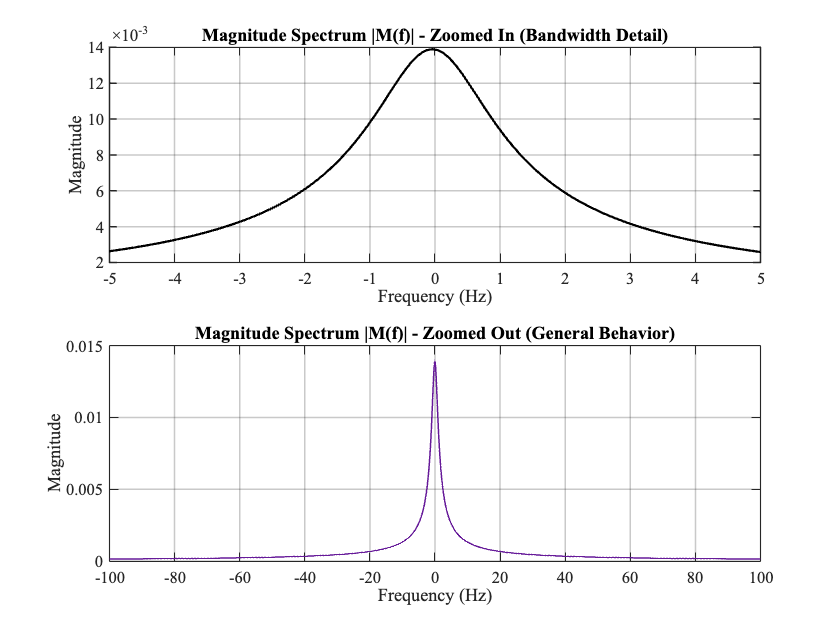

% Frequency Domain Analysis
L = length(t);
f = (-L/2 : L/2 - 1) * (Fs / L); % Frequency vector
M_f = fftshift(fft(m_norm));     % FFT calculation
M_mag = abs(M_f)/L;              % Magnitude spectrum

% Plot Spectrum (Two Views)
figure('Name', 'Frequency Domain Analysis');

% View 1: Zoomed In (To see the main bandwidth)
subplot(2,1,1);
plot(f, M_mag, 'LineWidth', 1.5, 'Color', 'k');
title('Magnitude Spectrum |M(f)| - Zoomed In (Bandwidth Detail)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([-5 5]); % Focus on low frequencies

% View 2: Zoomed Out (To see general behavior)
subplot(2,1,2);
plot(f, M_mag, 'LineWidth', 1.0, 'Color', [0.4 0.1 0.6]); % Purple
title('Magnitude Spectrum |M(f)| - Zoomed Out (General Behavior)');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;
xlim([-100 100]); % Wider range to show decay behavior

% Note: You can remove xlim completely to see up to Fs/2 (500 Hz)

% Bandwidth Calculation (99% Energy)
total_energy = sum(M_mag.^2);
current_energy = 0;
bw_index = 0;
center_idx = floor(L/2) + 1;

for k = 0:floor(L/2)
    if k == 0
        current_energy = current_energy + M_mag(center_idx)^2;
    else
        current_energy = current_energy + M_mag(center_idx+k)^2 + M_mag(center_idx-k)^2;
    end
    
    if current_energy >= 0.99 * total_energy
        bw_index = k;
        break;
    end
end

BW_eff = bw_index * (Fs/L);
Nyquist_Rate = 2 * BW_eff;

%% 6. Display Results
disp(['Effective Bandwidth (99% Energy): ', num2str(BW_eff), ' Hz']);

Effective Bandwidth (99% Energy): 60.7497 Hz


disp(['Minimum Sampling Rate (Nyquist):  ', num2str(Nyquist_Rate), ' Hz']);

Minimum Sampling Rate (Nyquist):  121.4995 Hz


## PART 2

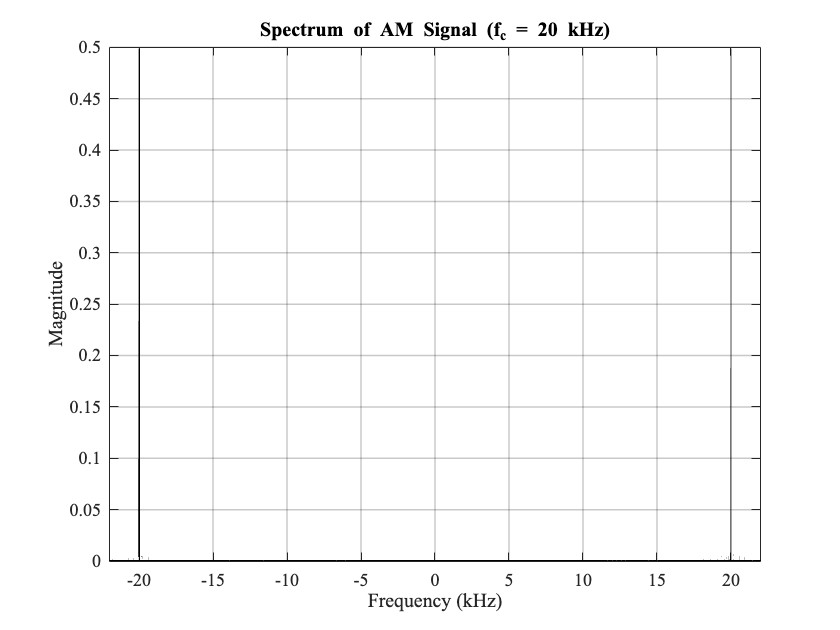

% Update Sampling Rate & Time Vector
% High sampling rate for kHz carrier visualization
Fs = 200000;            % 20 kHz
t = T_start:1/Fs:T_end; % Re-create time vector

% Re-generate Normalized Message Signal
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
m_norm = m_raw / max(abs(m_raw)); 

% Define Modulation Parameters
fc = 20000;     % Carrier Frequency = 20 kHz
mu = 0.85;      % Modulation Index
Ac = 1;         % Carrier Amplitude

% Generate AM Signal
s_am = Ac * (1 + mu * m_norm) .* cos(2*pi * fc * t);

% Plot Frequency Domain (kHz Scale)
L = length(t);
f = (-L/2 : L/2 - 1) * (Fs / L);
S_f = fftshift(fft(s_am));
S_mag = abs(S_f)/L;

figure('Name', 'AM Modulation - Frequency Domain');
plot(f/1000, S_mag, 'k', 'LineWidth', 1.2);
title(['Spectrum of AM Signal (f_c = ' num2str(fc/1000) ' kHz)']);
xlabel('Frequency (kHz)'); 
ylabel('Magnitude');
grid on;
xlim([-(fc/1000 + 2) (fc/1000 + 2)]); 

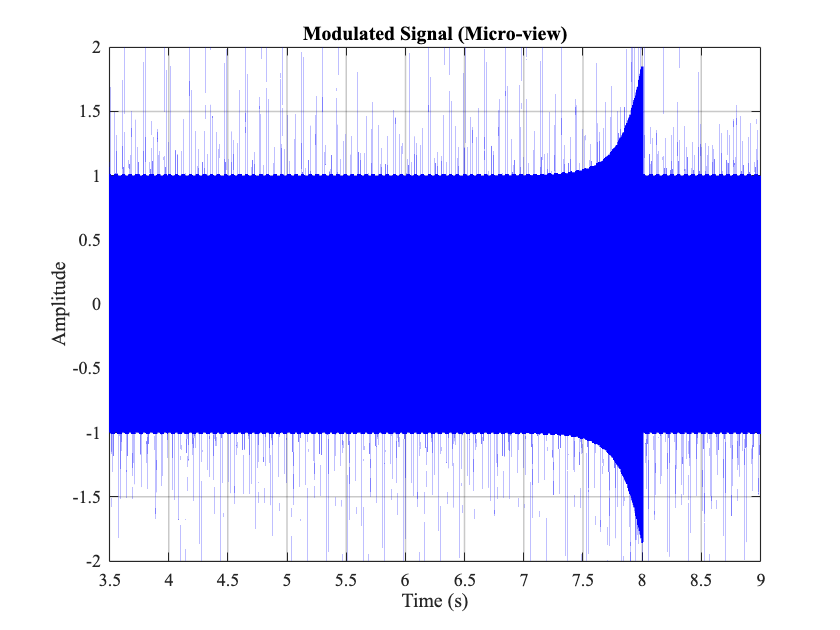

% Plot Time Domain (Zoomed - Signal ONLY)
figure('Name', 'AM Signal - Time Domain (Zoomed)');
plot(t, s_am, 'b'); % Only the modulated signal is plotted here
% 'hold on' and the envelope plot command have been removed.

title('Modulated Signal (Micro-view)');
xlabel('Time (s)');
ylabel('Amplitude');
xlim([3.5 9]); % 2ms window zoom
grid on;

## PART 3

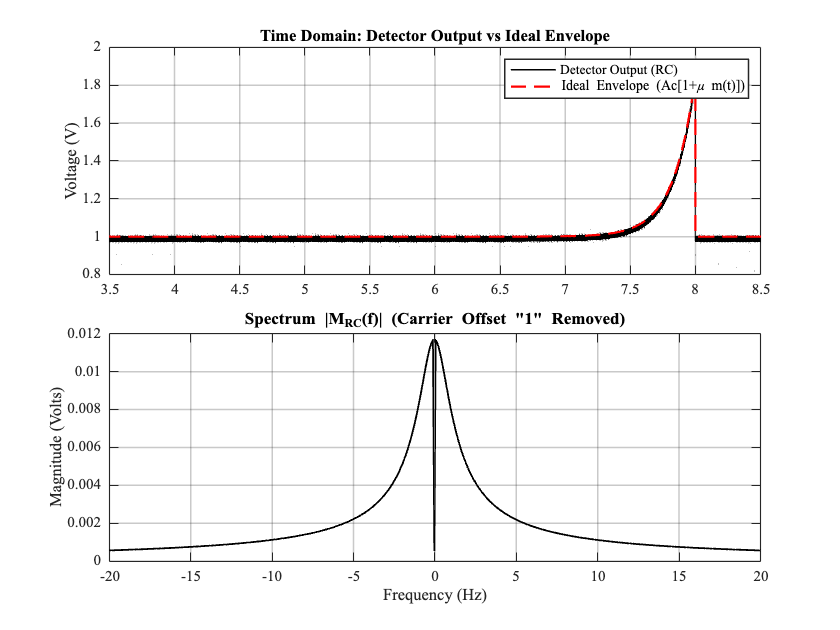

% 1. Setup Parameters
Fs = 200000;              
t = 0:1/Fs:12;            
fc = 20000;               
Ac = 1; mu = 0.85;        

% Create Message Signal
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); % Peak = 1
else
    m_norm = m_raw;
end

% Create AM Signal
s_am = Ac * (1 + mu * m_norm) .* cos(2*pi * fc * t);

% 2. Envelope Detector Implementation (RC Circuit)
tau = 0.002;          % Time constant (2ms)
decay = exp(-(1/Fs)/tau);
y_env = zeros(size(t));

% Charging/Discharging Loop
for i = 2:length(t)
    if s_am(i) > y_env(i-1)
        y_env(i) = s_am(i); % Charging
    else
        y_env(i) = y_env(i-1) * decay; % Discharging
    end
end

% 3. Frequency Analysis (The Correction)
L = length(t);

% --- IMPORTANT FIX ---
% We subtract Ac (which is 1) to remove the Carrier Offset.
% We do NOT use 'mean()' so that the message's own DC (0.013) is preserved.
y_env_corrected = y_env - Ac; 

% FFT Calculation
M_f = fftshift(fft(y_env_corrected)); 
M_mag = abs(M_f) / L;       % Normalize by Length
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% 4. Visualization
figure('Name', 'Part 3: Envelope Detector Results', 'Color', 'w');
tiledlayout(2,1, 'TileSpacing', 'compact');

% Plot 1: Time Domain
nexttile;
plot(t, y_env, 'k', 'LineWidth', 1); hold on;
plot(t, Ac*(1+mu*m_norm), 'r--', 'LineWidth', 1.5);
title('Time Domain: Detector Output vs Ideal Envelope');
legend('Detector Output (RC)', 'Ideal Envelope (Ac[1+\mu m(t)])');
xlim([3.5 8.5]); 
grid on;
ylabel('Voltage (V)');

% Plot 2: Frequency Domain
nexttile;
plot(f_axis, M_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); % Zoom on Baseband
title('Spectrum |{M}_{RC}(f)| (Carrier Offset "1" Removed)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Volts)');

output = sprintf(['------------------------------------------------\n', ...
                  'Zoomed View Analysis:\n', ...
                  '1. Gray lines: The high-frequency carrier signal.\n', ...
                  '2. Red dashed line: The perfect envelope we want to recover.\n', ...
                  '3. Blue line: The capacitor voltage.\n', ...
                  '   - Notice how the blue line rises with the carrier (Charging).\n', ...
                  '   - Then it slowly decays (Discharging) until the next carrier peak.\n', ...
                  '   - This "sawtooth" shape is the ripple caused by the RC time constant.\n', ...
                  '------------------------------------------------']);
disp(output);

------------------------------------------------
Zoomed View Analysis:
1. Gray lines: The high-frequency carrier signal.
2. Red dashed line: The perfect envelope we want to recover.
3. Blue line: The capacitor voltage.
   - Notice how the blue line rises with the carrier (Charging).
   - Then it slowly decays (Discharging) until the next carrier peak.
   - This "sawtooth" shape is the ripple caused by the RC time constant.
------------------------------------------------


## PART 4

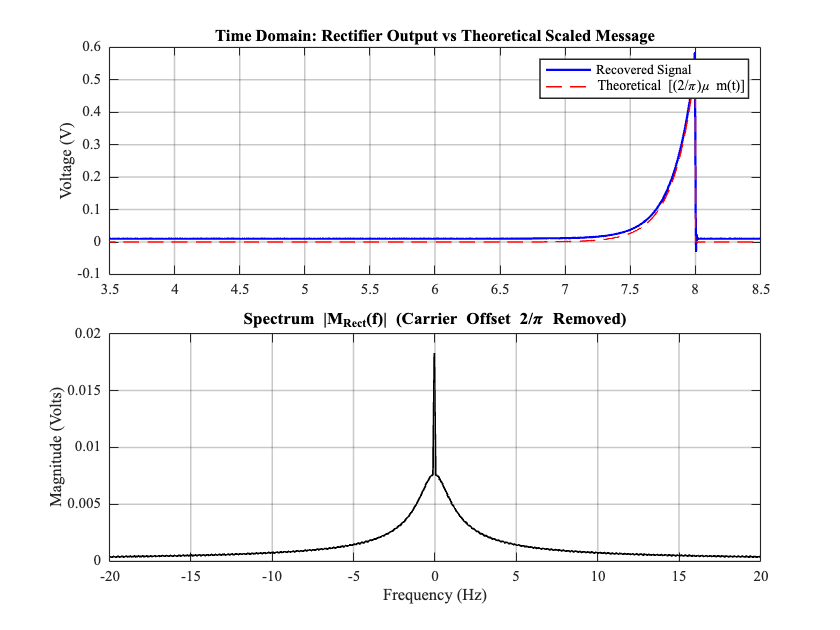

% 1. Setup Parameters
Fs = 200000;              
t = 0:1/Fs:12;            
fc = 20000;               
Ac = 1; mu = 0.85;        

% Create Message Signal
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); 
else
    m_norm = m_raw;
end

% Create AM Signal
s_am = Ac * (1 + mu * m_norm) .* cos(2*pi * fc * t);

% 2. Demodulation Implementation
% Step A: Rectification (Absolute Value)
y_rect = abs(s_am);

% Step B: Low Pass Filtering
% Using 4th order Butterworth to remove high freq ripples
[b, a] = butter(4, 100/(Fs/2)); 
y_filt = filtfilt(b, a, y_rect);

% 3. Frequency Analysis (The Correction)
L = length(t);

% --- CRITICAL FIX ---
% The DC component of a rectified cosine is (2/pi) * Amplitude.
% We subtract (2/pi)*Ac to remove the Carrier Offset.
carrier_offset = (2/pi) * Ac;
y_final = y_filt - carrier_offset; 

% FFT Calculation
M_f = fftshift(fft(y_final)); 
M_mag = abs(M_f) / L;       % Normalize by Length
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% 4. Visualization
figure('Name', 'Part 4: Rectifier Results', 'Color', 'w');
tiledlayout(2,1, 'TileSpacing', 'compact');

% Plot 1: Time Domain
nexttile;
plot(t, y_final, 'b', 'LineWidth', 1.5); hold on;
% We plot the theoretical scaled message for comparison: (2/pi)*mu*m(t)
plot(t, (2/pi)*Ac*mu*m_norm, 'r--', 'LineWidth', 1.0);
title('Time Domain: Rectifier Output vs Theoretical Scaled Message');
legend('Recovered Signal', 'Theoretical [(2/\pi)\mu m(t)]');
xlim([3.5 8.5]); 
grid on;
ylabel('Voltage (V)');

% Plot 2: Frequency Domain
nexttile;
plot(f_axis, M_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); % Zoom on Baseband
title('Spectrum |M_{Rect}(f)| (Carrier Offset 2/\pi Removed)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Volts)');

output = sprintf(['------------------------------------------------\n', ...
                  'Part 4 Analysis:\n', ...
                  '1. Rectification (|.|): Moves the message spectrum to baseband (DC) and creates harmonics at 2fc, 4fc, etc.\n', ...
                  '2. LPF: Removes the high-frequency harmonics (2fc = 40kHz), leaving only the baseband message.\n', ...
                  '\n', ...
                  'Under what conditions does this recover the message correctly?\n', ...
                  '-> The modulation index (mu) must be <= 1.\n', ...
                  '-> If mu > 1, the carrier phase reverses ("Overmodulation").\n', ...
                  '-> The absolute value operator destroys phase information, turning negative lobes positive.\n', ...
                  '-> This causes severe distortion in the recovered signal.\n', ...
                  '------------------------------------------------']);
disp(output);

------------------------------------------------
Part 4 Analysis:
1. Rectification (|.|): Moves the message spectrum to baseband (DC) and creates harmonics at 2fc, 4fc, etc.
2. LPF: Removes the high-frequency harmonics (2fc = 40kHz), leaving only the baseband message.

Under what conditions does this recover the message correctly?
-> The modulation index (mu) must be <= 1.
-> If mu > 1, the carrier phase reverses ("Overmodulation").
-> The absolute value operator destroys phase information, turning negative lobes positive.
-> This causes severe distortion in the recovered signal.
------------------------------------------------


## PART 5

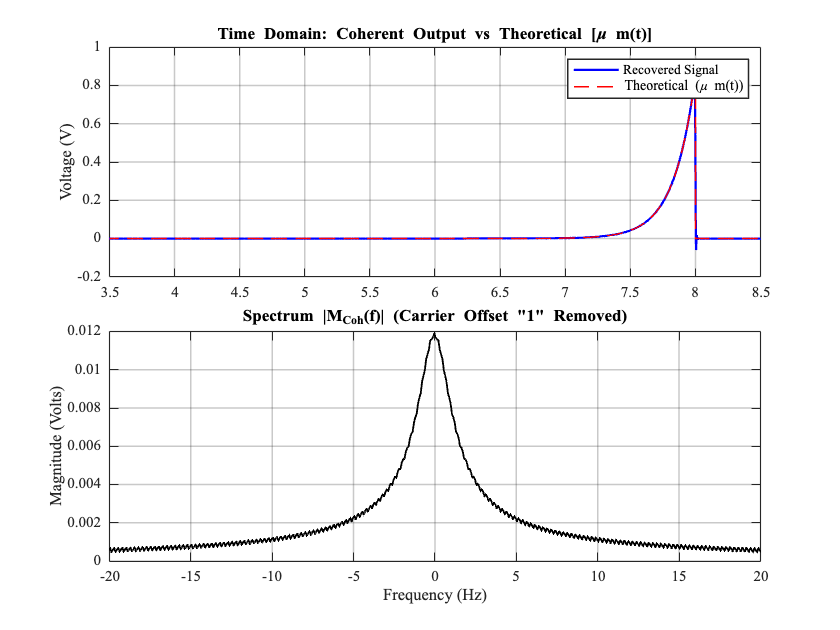

% 1. Setup Parameters
Fs = 200000;              
t = 0:1/Fs:12;            
fc = 20000;               
Ac = 1; mu = 0.85;        

% Create Message Signal
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); 
else
    m_norm = m_raw;
end

% Create AM Signal
s_am = Ac * (1 + mu * m_norm) .* cos(2*pi * fc * t);

% 2. Coherent Demodulation
% Step A: Mixing with Local Oscillator
% We multiply by 2*cos to cancel the 0.5 factor.
% Signal becomes: Ac[1 + \mu m(t)] * (1 + cos(2wc t))
y_mix = s_am .* (2 * cos(2*pi * fc * t));

% Step B: Low Pass Filtering
[b, a] = butter(4, 100/(Fs/2)); 
y_filt = filtfilt(b, a, y_mix);

% 3. Frequency Analysis (The Correction)
L = length(t);

% --- CRITICAL FIX ---
% The filtered output is Ac + Ac*\mu*m(t).
% We subtract Ac (which is 1) to remove the Carrier Offset.
y_final = y_filt - Ac; 

% FFT Calculation
M_f = fftshift(fft(y_final)); 
M_mag = abs(M_f) / L;       % Normalize by Length
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% 4. Visualization
figure('Name', 'Part 5: Coherent Detection Results', 'Color', 'w');
tiledlayout(2,1, 'TileSpacing', 'compact');

% Plot 1: Time Domain
nexttile;
plot(t, y_final, 'b', 'LineWidth', 1.5); hold on;
% Theoretical expectation: \mu * m(t)
plot(t, mu * m_norm, 'r--', 'LineWidth', 1.0);
title('Time Domain: Coherent Output vs Theoretical [\mu m(t)]');
legend('Recovered Signal', 'Theoretical (\mu m(t))');
xlim([3.5 8.5]); 
grid on;
ylabel('Voltage (V)');

% Plot 2: Frequency Domain
nexttile;
plot(f_axis, M_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); % Zoom on Baseband
title('Spectrum |M_{Coh}(f)| (Carrier Offset "1" Removed)');
xlabel('Frequency (Hz)'); ylabel('Magnitude (Volts)');

## PART 6

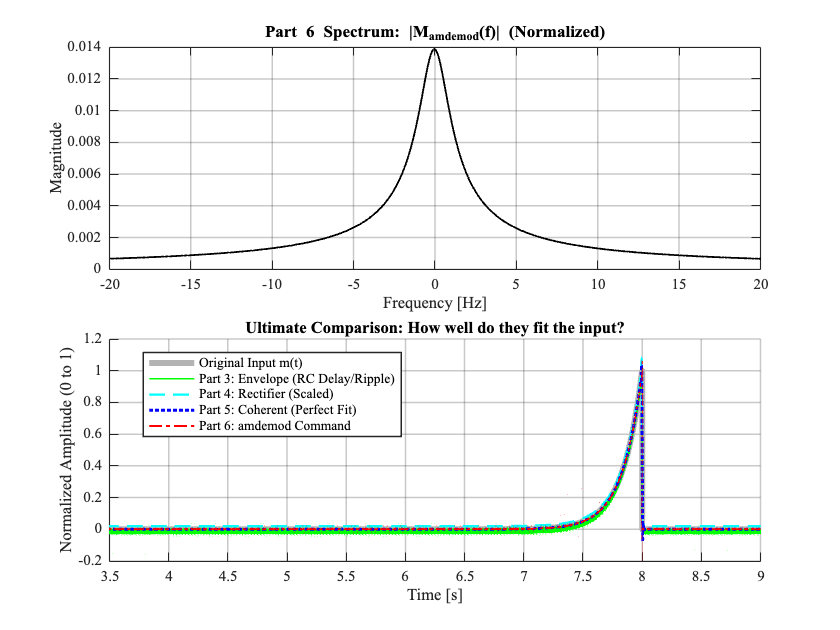

% 1. Setup Parameters
Fs = 200000;              
t = 0:1/Fs:12;            
fc = 20000;               
Ac = 1; mu = 0.85;        

% Create Message Signal (m_norm)
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0, m_norm = m_raw / max(abs(m_raw)); else, m_norm = m_raw; end

% Create AM Signal
s_am = Ac * (1 + mu * m_norm) .* cos(2*pi * fc * t);

%% --- RE-RUNNING PREVIOUS METHODS (For Comparison Plot) ---

% >> Method 3: Envelope Detector (RC)
tau = 0.002; decay = exp(-(1/Fs)/tau);
y_env = zeros(size(t));
for i = 2:length(t)
    if s_am(i) > y_env(i-1), y_env(i) = s_am(i); else, y_env(i) = y_env(i-1)*decay; end
end
% Normalize M3 to match original m(t): Remove Ac, divide by mu
m3_recovered = (y_env - Ac) / mu;

% >> Method 4: Rectifier + LPF
[b, a] = butter(4, 100/(Fs/2)); 
y_rect = abs(s_am);
y_rect_filt = filtfilt(b, a, y_rect);
% Normalize M4: Remove (2/pi)Ac, divide by (2/pi)mu
scale_rect = 2/pi;
m4_recovered = (y_rect_filt - scale_rect*Ac) / (scale_rect*mu);

% >> Method 5: Coherent Detection
y_mix = s_am .* (2 * cos(2*pi * fc * t));
y_coh_filt = filtfilt(b, a, y_mix);
% Normalize M5: Remove Ac, divide by mu
m5_recovered = (y_coh_filt - Ac) / mu;

% >> Method 6: amdemod Command
y_demod_raw = amdemod(s_am, fc, Fs, 0, Ac);
% Normalize M6: output is Ac*mu*m(t), so divide by Ac*mu
m6_recovered = y_demod_raw / (Ac * mu);

%% --- VISUALIZATION ---
figure('Name', 'Part 6 & Ultimate Comparison', 'Color', 'w');
tiledlayout(2, 1, 'TileSpacing', 'compact');

% Plot 1: Part 6 Specific Analysis (Spectrum)
% We calculate spectrum for amdemod result
L = length(t);
M6_f = fftshift(fft(m6_recovered));
M6_mag = abs(M6_f) / L;
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

nexttile;
plot(f_axis, M6_mag, 'k', 'LineWidth', 1.2);
grid on; xlim([-20 20]);
title('Part 6 Spectrum: |M_{amdemod}(f)| (Normalized)');
xlabel('Frequency [Hz]'); ylabel('Magnitude');

% Plot 2: THE ULTIMATE COMPARISON (Time Domain)
nexttile;
hold on;

% 1. Reference (Original Message) - Thick Gray Line
p1 = plot(t, m_norm, 'Color', [0.7 0.7 0.7], 'LineWidth', 4);

% 2. Method 3 (Envelope) - Green (Shows Ripple & Delay)
p2 = plot(t, m3_recovered, 'g', 'LineWidth', 1);

% 3. Method 4 (Rectifier) - Cyan Dashed
p3 = plot(t, m4_recovered, 'c--', 'LineWidth', 1.5);

% 4. Method 5 (Coherent) - Blue Dotted (Should be perfect)
p4 = plot(t, m5_recovered, 'b:', 'LineWidth', 2);

% 5. Method 6 (amdemod) - Red Dash-Dot (Should match Coherent)
p5 = plot(t, m6_recovered, 'r-.', 'LineWidth', 1.2);

hold off;
grid on;
xlim([3.5 9]); % Zoom on the pulse
title('Ultimate Comparison: How well do they fit the input?');
ylabel('Normalized Amplitude (0 to 1)');
xlabel('Time [s]');

% Interactive Legend
legend([p1, p2, p3, p4, p5], ...
    {'Original Input m(t)', ...
     'Part 3: Envelope (RC Delay/Ripple)', ...
     'Part 4: Rectifier (Scaled)', ...
     'Part 5: Coherent (Perfect Fit)', ...
     'Part 6: amdemod Command'}, ...
     'Location', 'best');

## PART 7

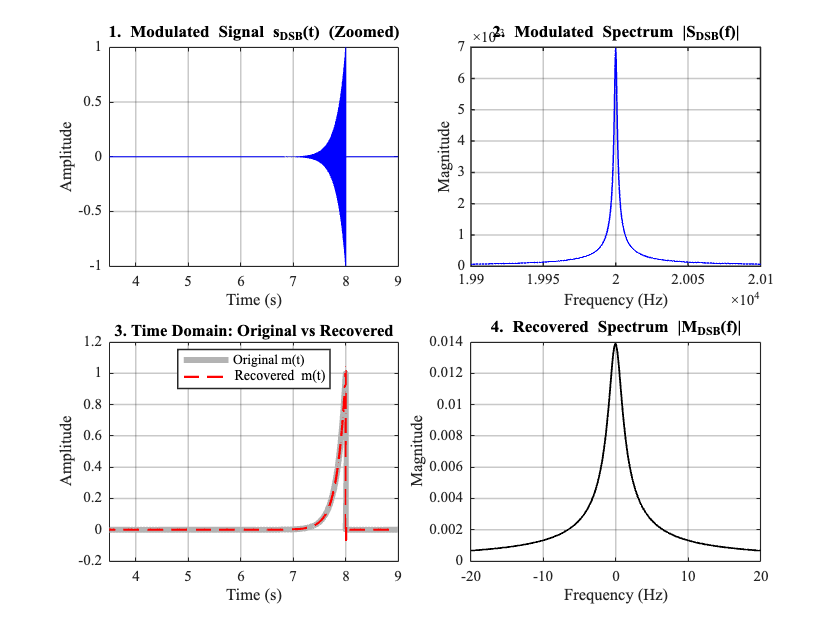

% 1. Setup Parameters
Fs = 200000;              % Sampling Rate
t = 0:1/Fs:12;            % Time Vector
fc = 20000;               % Carrier Frequency
% Note: In DSB-SC, we typically just multiply m(t) by cos(wt).
% We assume Ac=1 effectively.

% 2. Message Signal Generation
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
% Normalize message to usually have peak 1
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); 
else
    m_norm = m_raw;
end

% 3. DSB-SC Modulation
% Formula: s(t) = m(t) * cos(2*pi*fc*t)
% (NO carrier offset like '1+...' in AM)
s_dsb = m_norm .* cos(2*pi * fc * t);

% 4. Coherent Demodulation
% Step A: Mixing (Multiply by Local Oscillator)
% Multiply by 2*cos to recover exact amplitude
v_mix = s_dsb .* (2 * cos(2*pi * fc * t));

% Step B: Low Pass Filtering
[b, a] = butter(4, 100/(Fs/2)); 
m_recovered = filtfilt(b, a, v_mix);

% 5. Frequency Analysis
L = length(t);
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% Spectrum of Modulated Signal (s_DSB)
S_dsb_f = fftshift(fft(s_dsb));
S_dsb_mag = abs(S_dsb_f) / L;

% Spectrum of Recovered Message (m_hat)
M_rec_f = fftshift(fft(m_recovered));
M_rec_mag = abs(M_rec_f) / L;

% 6. Visualization (The 4 Requested Plots)
figure('Name', 'Part 7: DSB-SC Analysis', 'Color', 'w');
tiledlayout(2, 2, 'TileSpacing', 'compact');

% --- Plot 1: s_DSB(t) ---
nexttile;
plot(t, s_dsb, 'b', 'LineWidth', 0.5);
grid on; 
xlim([3.5 9]); % Zoom in to see the high frequency oscillation
title('1. Modulated Signal s_{DSB}(t) (Zoomed)');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 2: |S_DSB(f)| ---
nexttile;
plot(f_axis, S_dsb_mag, 'b', 'LineWidth', 1);
grid on; 
xlim([19900 20100]); % Zoom around Carrier (20 kHz)
title('2. Modulated Spectrum |S_{DSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');
% Note: You should see two sidebands and NO central carrier spike.

% --- Plot 3: Message & Recovered Time Domain ---
nexttile;
plot(t, m_norm, 'Color', [0.7 0.7 0.7], 'LineWidth', 4); hold on;
plot(t, m_recovered, 'r--', 'LineWidth', 1.5);
grid on; 
xlim([3.5 9]); 
title('3. Time Domain: Original vs Recovered');
legend('Original m(t)', 'Recovered {m}(t)', 'Location', 'best');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 4: |M_hat(f)| ---
nexttile;
plot(f_axis, M_rec_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); % Baseband zoom
title('4. Recovered Spectrum |{M}_{DSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');

## PART 8

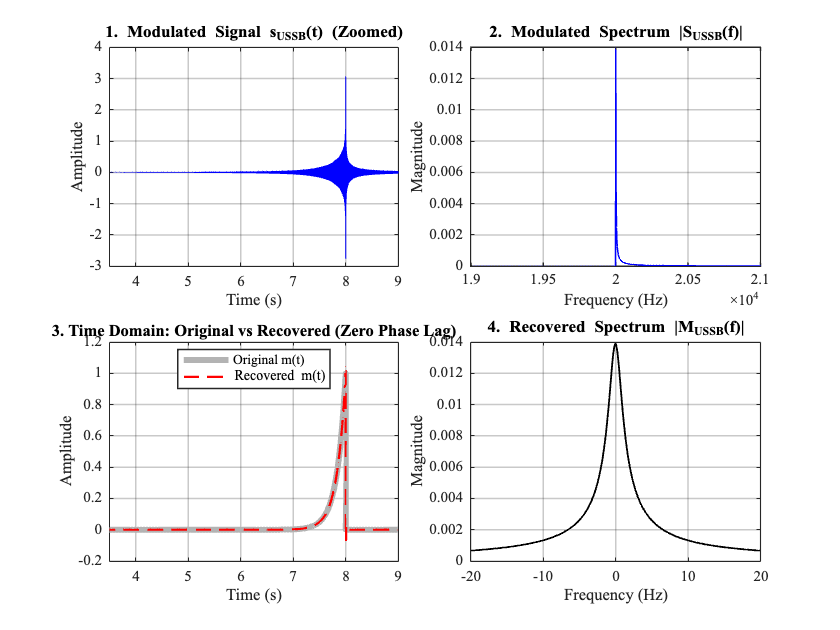

% 1. Setup Parameters
Fs = 200000;              % Sampling Rate
t = 0:1/Fs:12;            % Time Vector
fc = 20000;               % Carrier Frequency

% 2. Message Signal Generation
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); 
else
    m_norm = m_raw;
end

% 3. USSB Modulation (Using ssbmod)
% We use 'upper' sideband.
s_ussb = ssbmod(m_norm, fc, Fs, 0, 'upper');

% 4. Coherent Demodulation (MANUAL Implementation for Perfect Fit)
% Note: 'ssbdemod' introduces filter delay. 
% To get a perfect overlay plot, we use manual mixing + filtfilt (zero-phase).

% Step A: Mix with Local Oscillator (Multiply by 2*cos)
v_mix = s_ussb .* (2 * cos(2*pi * fc * t));

% Step B: Zero-Phase Low Pass Filtering
% This removes the high-frequency components AND cancels the time delay.
[b, a] = butter(4, 100/(Fs/2)); 
m_recovered = filtfilt(b, a, v_mix);

% 5. Frequency Analysis
L = length(t);
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% Spectrum of Modulated Signal
S_ussb_f = fftshift(fft(s_ussb));
S_ussb_mag = abs(S_ussb_f) / L;

% Spectrum of Recovered Signal
M_rec_f = fftshift(fft(m_recovered));
M_rec_mag = abs(M_rec_f) / L;

% 6. Visualization (4 Requested Plots)
figure('Name', 'Part 8: USSB Modulation (Perfect Fit)', 'Color', 'w');
tiledlayout(2, 2, 'TileSpacing', 'compact');

% --- Plot 1: s_USSB(t) ---
nexttile;
plot(t, s_ussb, 'b', 'LineWidth', 0.5);
grid on; 
xlim([3.5 9]); 
title('1. Modulated Signal s_{USSB}(t) (Zoomed)');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 2: |S_USSB(f)| ---
nexttile;
plot(f_axis, S_ussb_mag, 'b', 'LineWidth', 1);
grid on; 
xlim([19000 21000]); % Shows only Upper Sideband
title('2. Modulated Spectrum |S_{USSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');

% --- Plot 3: Time Domain Comparison (The FIT) ---
nexttile;
plot(t, m_norm, 'Color', [0.7 0.7 0.7], 'LineWidth', 4); hold on; % Gray thick line
plot(t, m_recovered, 'r--', 'LineWidth', 1.5);                   % Red dashed line
grid on; 
xlim([3.5 9]); 
title('3. Time Domain: Original vs Recovered (Zero Phase Lag)');
legend('Original m(t)', 'Recovered {m}(t)', 'Location', 'best');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 4: Recovered Spectrum ---
nexttile;
plot(f_axis, M_rec_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); 
title('4. Recovered Spectrum |{M}_{USSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');

## PART 9

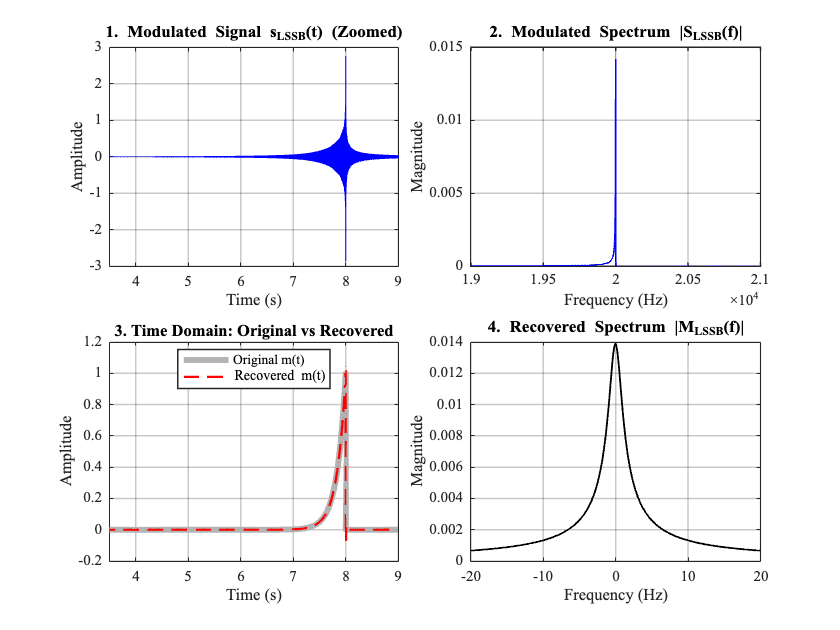

% 1. Setup Parameters
Fs = 200000;              % Sampling Rate
t = 0:1/Fs:12;            % Time Vector
fc = 20000;               % Carrier Frequency

% 2. Message Signal Generation
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0
    m_norm = m_raw / max(abs(m_raw)); 
else
    m_norm = m_raw;
end

% 3. LSSB Modulation (Using ssbmod with 'lower')
% Syntax: y = ssbmod(x, Fc, Fs, Ini_Phase, 'lower')
% We specify 'lower' to keep the Lower Side Band (f < fc)
s_lssb = ssbmod(m_norm, fc, Fs, 0);

% 4. Coherent Demodulation (Manual for Perfect Fit)
% Step A: Mix with Local Oscillator (Multiply by 2*cos)
v_mix = s_lssb .* (2 * cos(2*pi * fc * t));

% Step B: Zero-Phase Low Pass Filtering
% Removes high freqs + cancels delay
[b, a] = butter(4, 100/(Fs/2)); 
m_recovered = filtfilt(b, a, v_mix);

% 5. Frequency Analysis
L = length(t);
f_axis = (-L/2 : L/2 - 1) * (Fs / L);

% Spectrum of Modulated Signal
S_lssb_f = fftshift(fft(s_lssb));
S_lssb_mag = abs(S_lssb_f) / L;

% Spectrum of Recovered Signal
M_rec_f = fftshift(fft(m_recovered));
M_rec_mag = abs(M_rec_f) / L;

% 6. Visualization (4 Requested Plots)
figure('Name', 'Part 9: LSSB Modulation', 'Color', 'w');
tiledlayout(2, 2, 'TileSpacing', 'compact');

% --- Plot 1: s_LSSB(t) ---
nexttile;
plot(t, s_lssb, 'b', 'LineWidth', 0.5);
grid on; 
xlim([3.5 9]); 
title('1. Modulated Signal s_{LSSB}(t) (Zoomed)');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 2: |S_LSSB(f)| ---
nexttile;
plot(f_axis, S_lssb_mag, 'b', 'LineWidth', 1);
grid on; 
% Zoom around Carrier (20 kHz)
xlim([19000 21000]); 
title('2. Modulated Spectrum |S_{LSSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');
% Note: Energy should be on the LEFT side (< 20kHz).

% --- Plot 3: Time Domain Comparison ---
nexttile;
plot(t, m_norm, 'Color', [0.7 0.7 0.7], 'LineWidth', 4); hold on;
plot(t, m_recovered, 'r--', 'LineWidth', 1.5);
grid on; 
xlim([3.5 9]); 
title('3. Time Domain: Original vs Recovered');
legend('Original m(t)', 'Recovered {m}(t)', 'Location', 'best');
ylabel('Amplitude'); xlabel('Time (s)');

% --- Plot 4: Recovered Spectrum ---
nexttile;
plot(f_axis, M_rec_mag, 'k', 'LineWidth', 1.2);
grid on; 
xlim([-20 20]); 
title('4. Recovered Spectrum |{M}_{LSSB}(f)|');
ylabel('Magnitude'); xlabel('Frequency (Hz)');

## PART 10

% 1. SETUP & MESSAGE GENERATION
Fs = 200000;            
t = 0:1/Fs:12;          
fc = 20000;             
Ac = 1; mu = 0.85;      

% Create Message m(t)
window = (t >= 4) & (t <= 8);
m_raw = (exp(-6*t) .* window) + (exp(6*t) .* window);
if max(abs(m_raw)) > 0, mN = m_raw / max(abs(m_raw)); else, mN = m_raw; end
E_msg = sum(mN.^2); 

% =====================================================================
% 2. MODULATION & DEMODULATION 
% =====================================================================
[b,a] = butter(4, 100/(Fs/2)); % LPF 100Hz

% --- A) AM ---
s_am = Ac * (1 + mu * mN) .* cos(2*pi * fc * t);
v_mix_am = s_am .* (2 * cos(2*pi * fc * t));
y_filt_am = filtfilt(b, a, v_mix_am);
mhat_am = (y_filt_am - Ac) / mu; 

% --- B) DSB-SC ---
s_dsb = mN .* cos(2*pi * fc * t);
v_mix_dsb = s_dsb .* (2 * cos(2*pi * fc * t));
mhat_dsb = filtfilt(b, a, v_mix_dsb);

% --- C) USSB ---
try
    s_ussb = ssbmod(mN, fc, Fs, 0, 'upper'); okU = true;
catch
    s_ussb = zeros(size(t)); okU = false;
end
v_mix_ussb = s_ussb .* (2 * cos(2*pi * fc * t));
mhat_ussb = filtfilt(b, a, v_mix_ussb);

% --- D) LSSB ---
try
    s_lssb = ssbmod(mN, fc, Fs, 0); okL = true;
catch
    s_lssb = zeros(size(t)); okL = false;
end
v_mix_lssb = s_lssb .* (2 * cos(2*pi * fc * t));
mhat_lssb = filtfilt(b, a, v_mix_lssb);

% =====================================================================
% 3. NMSE CALCULATION
% =====================================================================
calc_nmse = @(ref, est) sum((ref - est).^2) / sum(ref.^2);
E_am  = calc_nmse(mN, mhat_am);
E_dsb = calc_nmse(mN, mhat_dsb);
E_u   = calc_nmse(mN, mhat_ussb);
E_l   = calc_nmse(mN, mhat_lssb);

fprintf('\n[Q1-10] NMSE SUMMARY:\n');


[Q1-10] NMSE SUMMARY:


fprintf('  AM : %.4e | DSB : %.4e | USSB : %.4e | LSSB : %.4e\n', E_am, E_dsb, E_u, E_l);

  AM : 3.4760e-02 | DSB : 5.4584e-03 | USSB : 5.4585e-03 | LSSB : 5.4585e-03


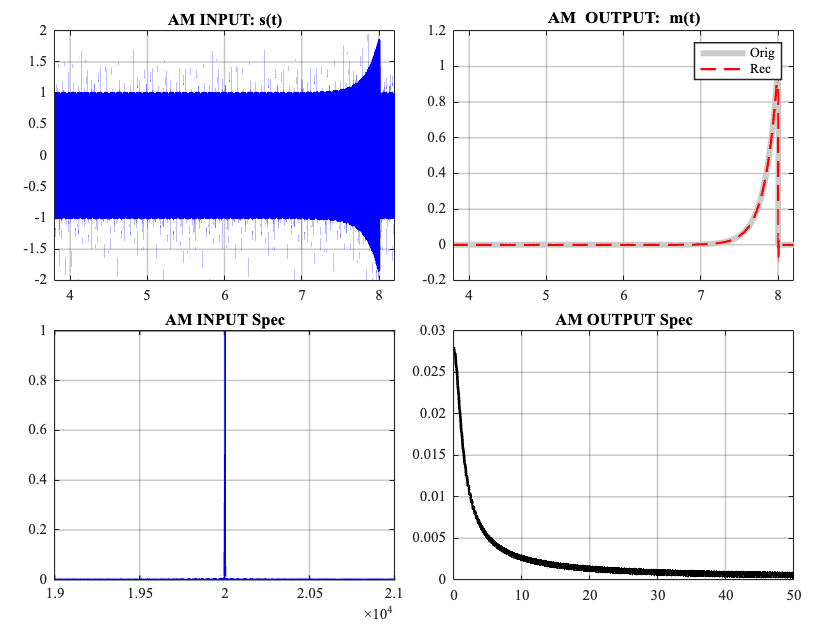


% =====================================================================
% 4. VISUALIZATION (FIXED INDEXING)
% =====================================================================
L = length(t);
% FIX: Use floor to ensure integer index
L_half = floor(L/2); 
f_vec = (0 : L_half) * (Fs/L); 

get_spec = @(x) 2*abs(fft(x)/L); 

% --- PLOT FUNCTION ---
plot_method = @(name, s_t, m_hat, spec_in, spec_out) ...
    create_plot(name, t, f_vec, s_t, m_hat, mN, spec_in, spec_out);

% 1. AM Plot
% FIX: Use L_half instead of L/2
S_in = get_spec(s_am); S_in = S_in(1:L_half+1);
M_out = get_spec(mhat_am); M_out = M_out(1:L_half+1);
plot_method('AM', s_am, mhat_am, S_in, M_out);

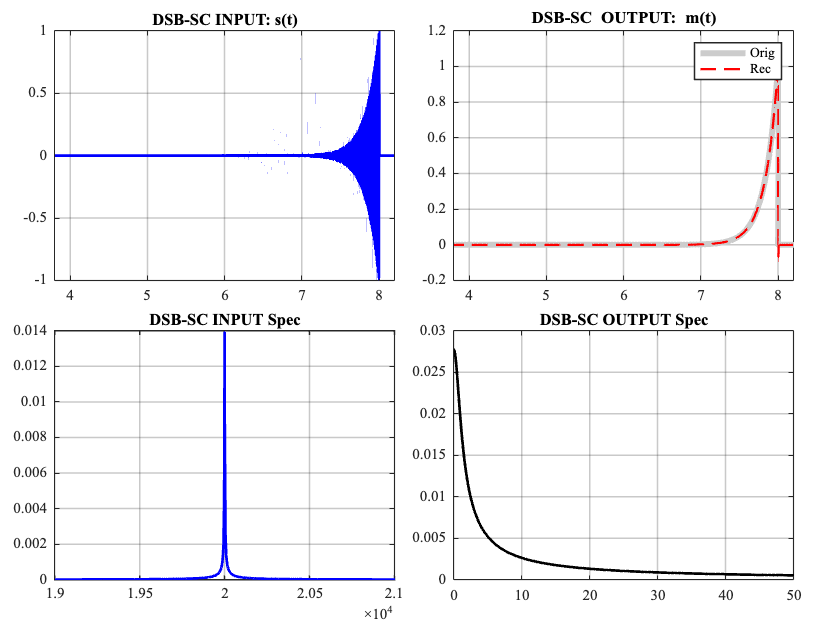


% 2. DSB-SC Plot
S_in = get_spec(s_dsb); S_in = S_in(1:L_half+1);
M_out = get_spec(mhat_dsb); M_out = M_out(1:L_half+1);
plot_method('DSB-SC', s_dsb, mhat_dsb, S_in, M_out);

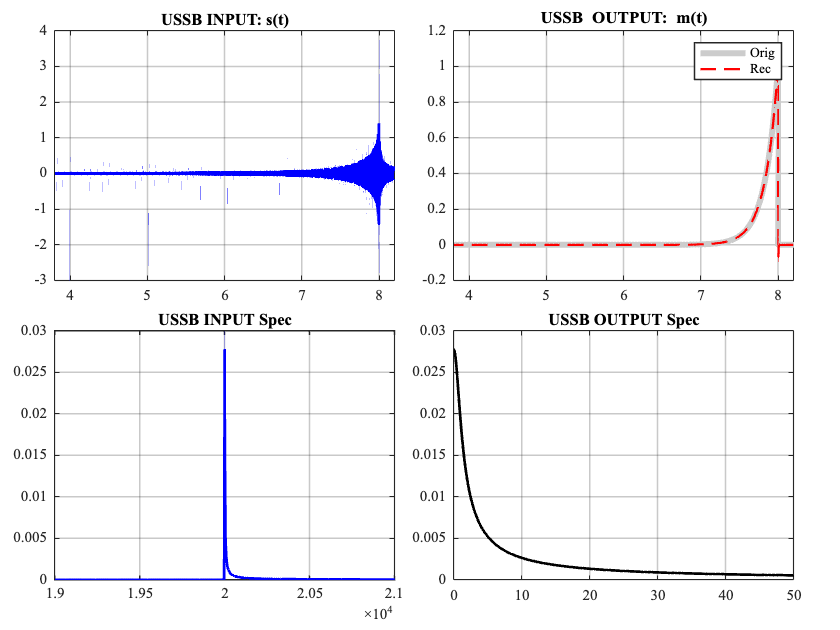


% 3. USSB Plot
S_in = get_spec(s_ussb); S_in = S_in(1:L_half+1);
M_out = get_spec(mhat_ussb); M_out = M_out(1:L_half+1);
plot_method('USSB', s_ussb, mhat_ussb, S_in, M_out);

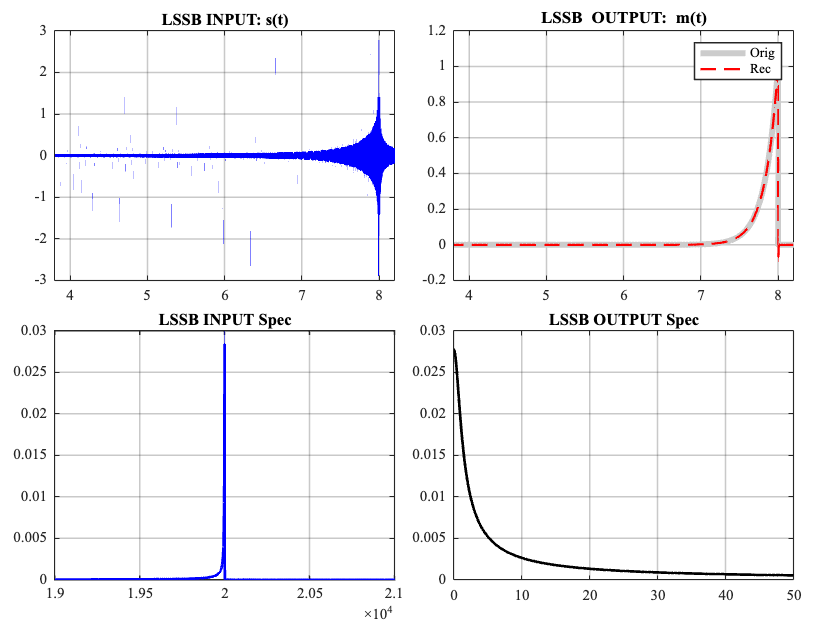


% 4. LSSB Plot
S_in = get_spec(s_lssb); S_in = S_in(1:L_half+1);
M_out = get_spec(mhat_lssb); M_out = M_out(1:L_half+1);
plot_method('LSSB', s_lssb, mhat_lssb, S_in, M_out);

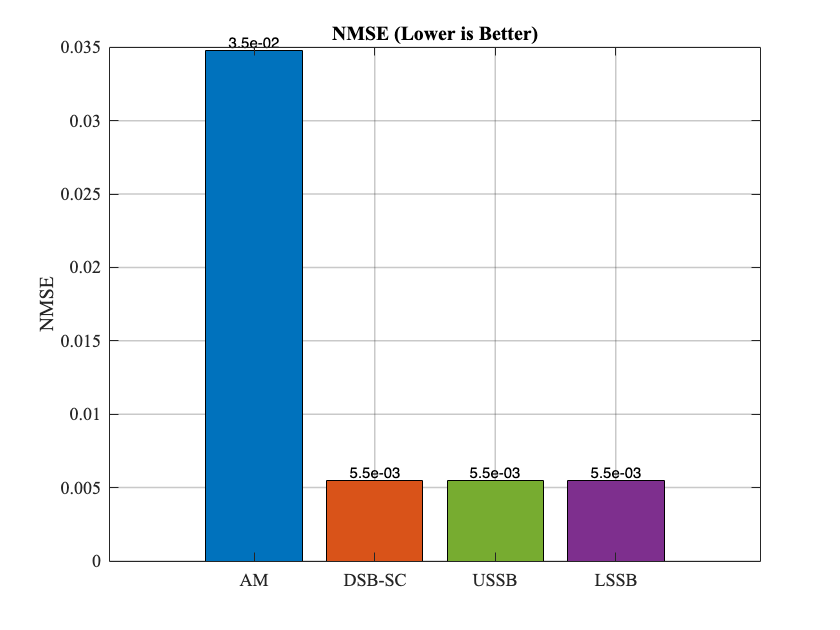


% 5. NMSE Bar Chart
figure('Name', 'NMSE Comparison', 'Color', 'w');
b = bar([E_am, E_dsb, E_u, E_l]);
b.FaceColor = 'flat';
b.CData = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0.4940 0.1840 0.5560];
set(gca, 'XTickLabel', {'AM', 'DSB-SC', 'USSB', 'LSSB'});
grid on; title('NMSE (Lower is Better)'); ylabel('NMSE');
text(1:4, [E_am, E_dsb, E_u, E_l], num2str([E_am; E_dsb; E_u; E_l], '%.1e'), ...
    'vert', 'bottom', 'horiz', 'center');


% =====================================================================
% LOCAL FUNCTION 
% =====================================================================
function create_plot(name, t, f, s_t, m_hat, m_ref, S_f, M_f)
    figure('Name', [name ' Analysis'], 'Color', 'w');
    tiledlayout(2, 2, 'Padding', 'compact', 'TileSpacing', 'compact');
    
    nexttile; plot(t, s_t, 'b'); grid on; xlim([3.8 8.2]); title([name ' INPUT: s(t)']);
    
    nexttile; plot(t, m_ref, 'Color',[.8 .8 .8],'LineWidth',4); hold on;
    plot(t, m_hat, 'r--','LineWidth',1.5); grid on; xlim([3.8 8.2]); 
    legend('Orig','Rec'); title([name ' OUTPUT: {m}(t)']);
    
    nexttile; plot(f, S_f, 'b'); grid on; xlim([19000 21000]); title([name ' INPUT Spec']);
    
    nexttile; plot(f, M_f, 'k'); grid on; xlim([0 50]); title([name ' OUTPUT Spec']);
end

## PART 11

% 1. Setup Parameters (Fixed Fs = 44100 as requested)
Fs_audio = 44100;      % Standard Audio Sampling Rate
duration = 5;          % Recording duration (seconds)
nBits = 16;            % Bit depth
nChannels = 1;         % Mono

disp('==================================================');

disp(['Preparing to record for ', num2str(duration), ' seconds...']);

Preparing to record for 5 seconds...


disp('Get ready...');

Get ready...


pause(1);

% 2. Recording
recObj = audiorecorder(Fs_audio, nBits, nChannels);
disp('>>> SPEAK NOW! (Recording...) <<<');

>>> SPEAK NOW! (Recording...) <<<


recordblocking(recObj, duration);
disp('>>> STOPPED. Processing signal... <<<');

>>> STOPPED. Processing signal... <<<


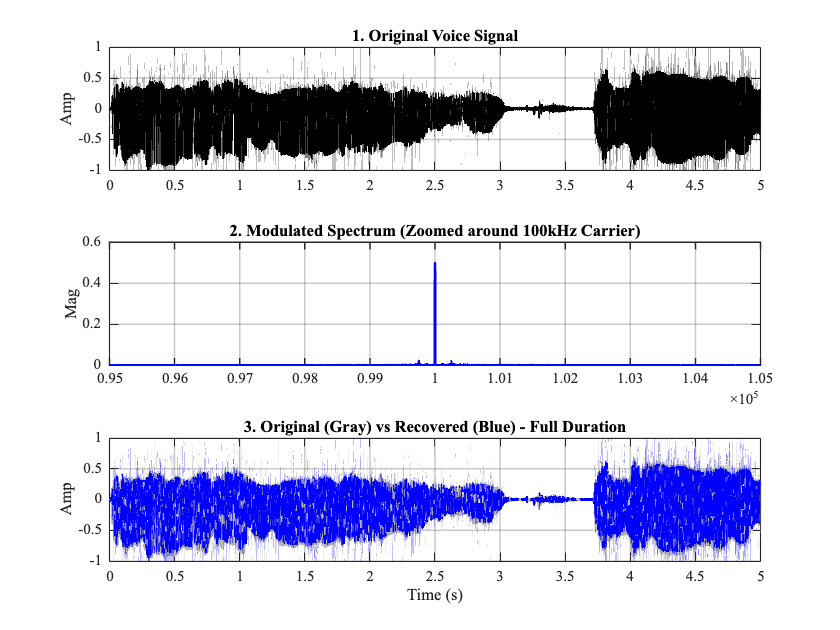


% 3. Pre-processing
m_audio = getaudiodata(recObj);
m_audio = m_audio - mean(m_audio);      % Remove DC offset

% Force Row Vector (prevent memory error)
m_audio = m_audio(:).'; 

m_norm = m_audio / max(abs(m_audio));   % Normalize (-1 to 1)

% 4. Upsampling for AM Simulation
% Carrier is 100kHz, so we need Fs > 200kHz. We use 400kHz.
Fs_sim = 400000; 
m_upsampled = resample(m_norm, Fs_sim, Fs_audio);
m_upsampled = m_upsampled(:).'; % Ensure Row Vector

% Create Time Vector
L = length(m_upsampled);
t = (0 : L-1) / Fs_sim;

% 5. AM Modulation
fc = 100000;   % Carrier = 100 kHz
Ac = 1; 
mu = 0.95;     

% Modulation
s_am = Ac * (1 + mu * m_upsampled) .* cos(2*pi * fc * t);

% 6. AM Demodulation
% Coherent Demodulation Simulation
y_demod = amdemod(s_am, fc, Fs_sim, 0, Ac);

% Downsample back to Audio Rate
m_recovered = resample(y_demod, Fs_audio, Fs_sim);

% 7. Visualization
figure('Name', 'Part 11: Audio AM Analysis', 'Color', 'w');
tiledlayout(3, 1, 'TileSpacing', 'compact');

% Plot 1: Original Audio (Full Duration)
nexttile;
t_audio = (0:length(m_norm)-1)/Fs_audio;
plot(t_audio, m_norm, 'k');
title('1. Original Voice Signal'); grid on; 
xlim([0 duration]); 
ylabel('Amp');

% Plot 2: Spectrum (Zoomed)
nexttile;
f_vec = (-L/2 : L/2 - 1) * (Fs_sim / L);
S_f = fftshift(abs(fft(s_am)/L));
plot(f_vec, S_f, 'b');
grid on; xlim([fc-5000, fc+5000]); 
title('2. Modulated Spectrum (Zoomed around 100kHz Carrier)');
ylabel('Mag');

% Plot 3: Comparison (FULL DURATION - Matches Plot 1)
nexttile;
t_rec = (0:length(m_recovered)-1)/Fs_audio;
len = min(length(t_audio), length(t_rec));

% Plot Original (Gray background)
plot(t_audio(1:len), m_norm(1:len), 'Color', [.7 .7 .7], 'LineWidth', 2); hold on;
% Plot Recovered (Blue dashed)
plot(t_rec(1:len), m_recovered(1:len), 'b--');

title('3. Original (Gray) vs Recovered (Blue) - Full Duration'); 
grid on;
xlim([0 duration]); % <--- CHANGED to show full 5 seconds
ylabel('Amp'); xlabel('Time (s)');

% 8. Playback & Save
disp('--------------------------------------------------');

--------------------------------------------------


disp('Playing Original Audio...');

Playing Original Audio...


sound(m_norm, Fs_audio);
pause(duration + 1);

disp('Playing Recovered Audio...');

Playing Recovered Audio...


sound(m_recovered, Fs_audio);

audiowrite('voice_orig.wav', m_norm, Fs_audio);
audiowrite('voice_rec.wav', m_recovered, Fs_audio);
disp('--------------------------------------------------');

--------------------------------------------------


disp('Files saved.');

Files saved.
